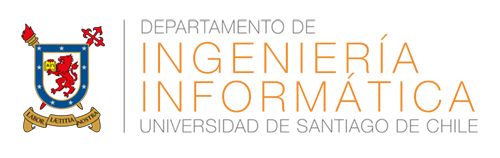

# Tarea N° 3

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

# Generales

 Precaución al reproducir las señales, archivos wav o sus resultados en audífonos o altavoces ya que puede ocasionar daño a su sistema de reproducción o más importante a sus oídos. 

Entregue un archivo .mlx de Matlab sin ningún adjunto (archivos .wav, archivos .m ni otros). Se evalúa los conceptos y fórmulas en formato de texto, los comentarios dentro del código, la exactitud y simpleza del algoritmo y la calidad de los gráficos generados. Muestre solo los valores más importantes.

# Problema

La respuesta al impulso relativa a la cabeza (o head related impulse response HRIR) es una medición realizada en laboratorio (una cámara anecoica donde todas las paredes absorben el sonido) donde un altavoz es ubicado a una cierta distancia en una orientación azimutal de ángulo *θ* (respecto al plano xy) y elevación de ángulo *ɸ* (ver Fig. 1)*.*

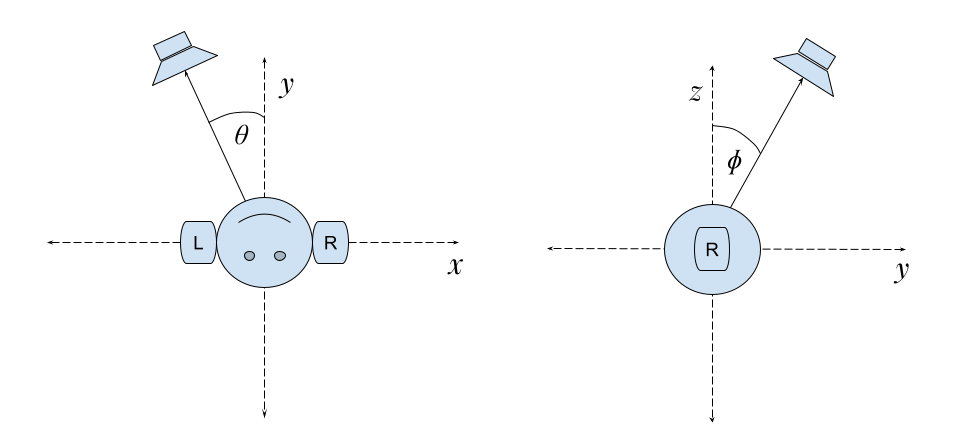

**Figura 1: Geometría del problema.**

Al reproducir una señal de impulso unitario por el altavoz y registrar su señal en un par de micrófonos intraurales en un receptor (ver Fig 2), podemos obtener un conjunto de respuestas al impulso $h^{\theta \phi}_l (n)$ y $h^{\theta \phi}_r (n)$.

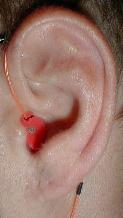

**Figura 2: Micrófono intraural.**

La interpolación de la HRIR $y_l (n)$ e $y_r (n)$, se obtiene mediante la convolución entre una señal de entrada monofónica $x(n)$ y el par de respuestas al impulso $h^{\theta \phi}_l (n)$ y $h^{\theta \phi}_r (n)$ para una dupla de ángulos *θ* y *ɸ* según el sistema:

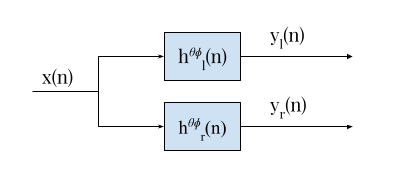

Así, se obtiene una señal de salida estereofónica mediante las operaciones $y_l (n) = x(n) \ast h^{\theta \phi}_l (n)$ para el canal izquierdo y $y_r (n) = x(n) \ast h^{\theta \phi}_r (n)$ para el canal derecho, donde la señal de salida $y(n)$ (estéreo) simula espacialmente la señal de entrada $x(n)$ como si se ubicara en los ángulos *θ* y *ɸ* (este efecto se aprecia de mejor forma utilizando audífonos)*.*

Considerando solamente el ángulo de elevación *ɸ *= 0 y los ángulos azimutales *θ *= 0:15:345, divida el archivo wav 'helicopter.wav' en 24 partes iguales de 1 segundo más 500 muestras de traslape, las cuales deberán ser convolucionadas con las respuestas al impulso $h^{\theta \phi}_l (n)$ y $h^{\theta \phi}_r (n)$ para los ángulos azimutales seleccionados (ver Fig. 3).

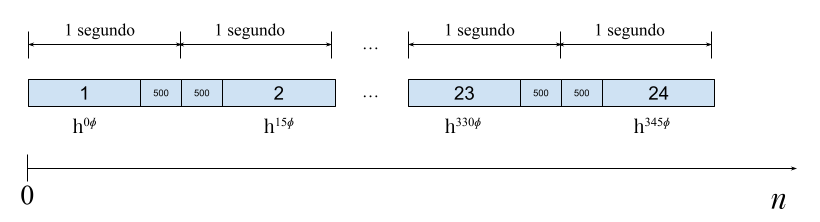

**Figura 3: División de la señal de entrada.**

Luego de realizada las convoluciones, combine la señal de salida de 24 segundos utilizando un crossfade en la zona de traslape, multiplicando la señal con rampas crecientes y decrecientes entre 0 y 1 (ver Fig. 4) utilizando la función de matlab linespace(inicio, termino, largo).

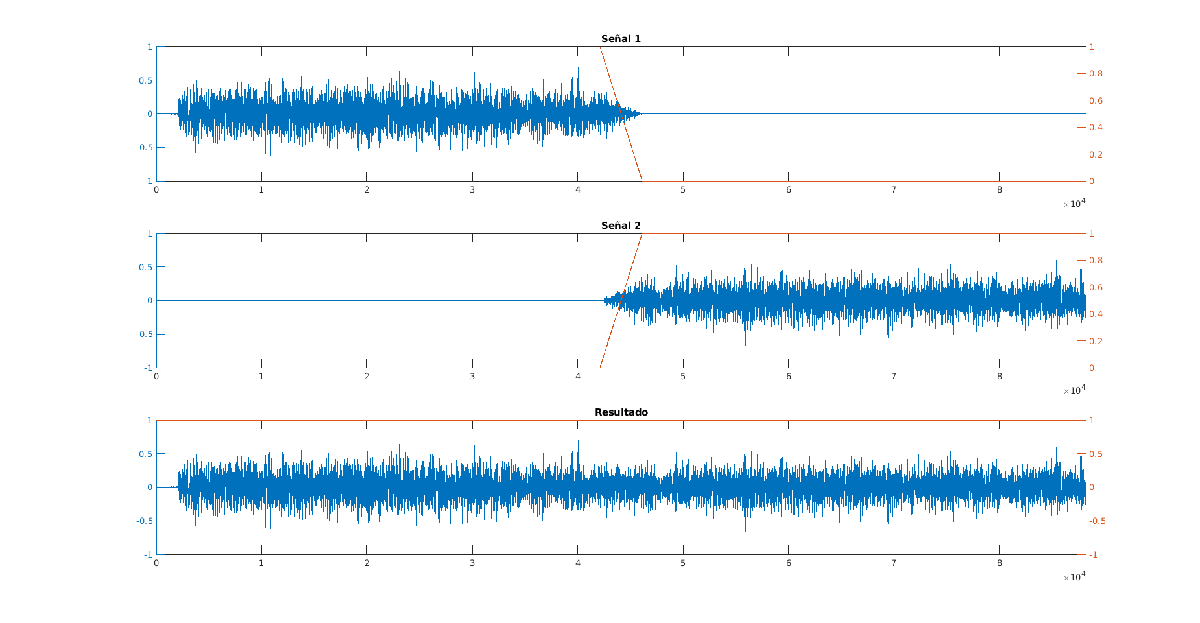

**Figura 4: Ejemplo de crossfade en la zona de traslape.**

El resultado debería ser similar a un efecto en donde la señal de entrada rodea a la persona que escuche mediante audifonos (ejemplo en el archivo salida.wav). Las mediciones de respuesta al impulso se encuentran en las variables tipo struct l_hrir_S para el canal izquierdo y r_hrir_S para el canal derecho contenidas en el archivo IRC_1002_R_HRIR.mat:

clearvars
load('IRC_1002_R_HRIR.mat')

Los vectores elev_v y azim_v contienen los valores de ángulos para *ɸ* y *θ* respectivamente y la matriz content_m contiene los valores de las respuestas al impulso en sus filas.

[y, Fs] = audioread('salida.wav');
player = audioplayer(y, Fs);
playblocking(player)

Dado el largo de la respuesta al impulso medida, para este caso utilice el parámetro 'full' en la funcion conv y luego seleccione la sección de audio del largo que sea necesario.

# Referencias

[1] http://recherche.ircam.fr/equipes/salles/listen/